`龙格库塔法是一种求解常微分方程的``数值解法``，微分方程可以是``线性``也可以是``非线性``的。`


$$$\dot{x}=f(x,u)$$$


`    在控制系统中，x指系统状态，u指系统输入。`

`四阶龙格库塔法：`


$$\\ x_{k+1}=x_{k}+\frac{h}{6}(K_1+K_2+K_3+K_4)
\\ K_1=f(x_k,u_1)
\\ K_2=f(x_k+\frac{h}{2}K_1,u2)
\\ K_3=f(x_k+\frac{h}{2}K_2,u3)
\\ K_4=f(x_k+h*K_3)
$$


        
$$$\\ u_1,u_2,u_3,u_4$为对应时刻的系统输入，当微分方程中存在输入信号u时，求解步长h不能取太大，否则误差将很大。
$$


`从微分方程的形式`$$\dot{x}=f(x,u)$$`可以看出，这是一个一阶微分方程，对于高阶微分方程如何求解？`

`    一个n阶微分方程可以化为n个一阶微分方程，相当于一个n阶控制系统，通过选取n个状态向量，从而得到n个一阶微分方程。例如，`


$$\ddot{z}+\dot{z}+z=u
$$


`    取状态向量`$$x_1=z,x_2=\dot{z}$$`，得`


$$\\ \dot{x_1}=\dot{z}=x_2
\\ \dot{x_2}=\ddot{z}=-z-\dot{z}+u=-x_1-x_2+u$$


`代码示例：`

`        以一个二阶非线性微分方程为例，通过取状态向量，化为2个一阶微分方程：`


$$\\ \dot{x_1}=x_2
\\ \dot{x_2}=\mu(1-x_{1}^{2})x_2-x_1
$$


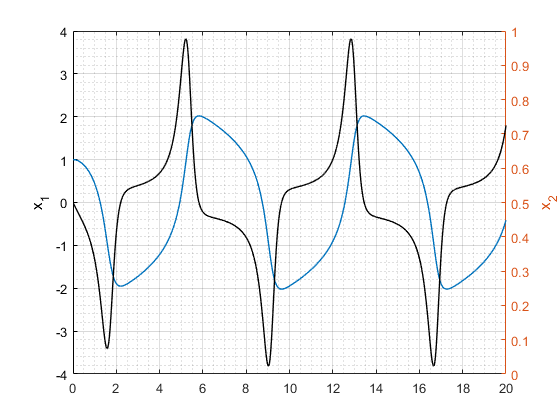

clc
clear all
close all

Tmax = 20;
h = 0.01;
T=[0:h:Tmax];   % 龙格库塔法求解区间[0,Tmax] 步长为h
X0=[1;0];       % 微分方程初始条件

[T_labrk4,x_labrk4] = lab_ode_rk4(@non_linear_d_func,T,X0);


plot(T_labrk4,x_labrk4(1,:),'LineWidth',1);
yyaxis left
ylabel('x_1');
hold on
plot(T_labrk4,x_labrk4(2,:),'LineWidth',1);
yyaxis right
ylabel('x_2');
hold off
grid on
grid minor

`代码示例：`

`    假设`$x=e^{t}$`，则`$\dot{x}=e^{t}=x
$(对比解析解和数值解)

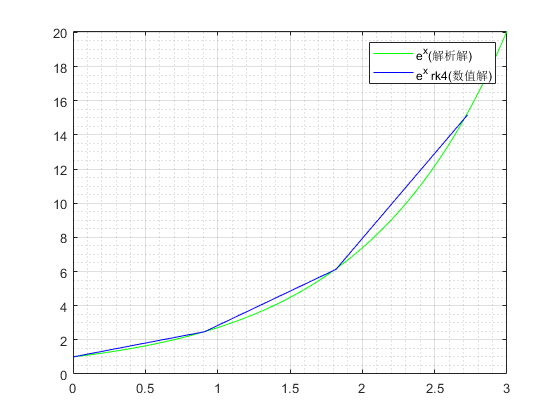

Tmax = 3;
t = 0:0.001:Tmax;
x = exp(t);
h = 0.909;
T = [0:h:Tmax];
X0 = 1;

[T_labrk4,x_labrk4] = lab_ode_rk4(@exp_diff,T,X0);

figure()
plot(t, x, 'g')
hold on
plot(T_labrk4, x_labrk4, 'b')
hold off
legend("e^{x}(解析解)", "e^{x} rk4(数值解)")
grid on
grid minor

function dx = exp_diff(t,x)
    dx = x;
end